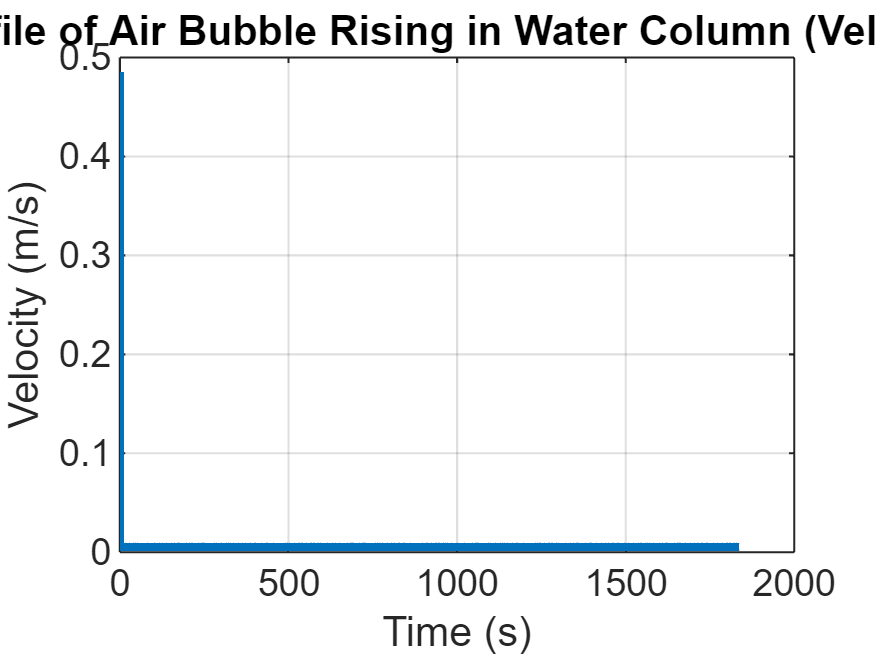

% Parameters
g = 9.81;               % gravitational acceleration (m/s^2)
rhoWater = 1000;         % density of water (kg/m^3)
rhoAir = 1.225;          % density of air (kg/m^3)
mu = 0.001;              % dynamic viscosity of water (Pa.s)
d = 100 * 10^-6;         % diameter of the bubble (m)
p0 = 101325;             % atmospheric pressure at the bottom (Pa)
h0 = 10;                 % height of the column (m)

% Velocity equation as a function of height h
velocityEquation = @(h, U) g * (1 - ((rhoAir * (p0 - rhoWater * g * h)) / p0) / rhoWater) ...
    - (3 * pi * mu * d) / (rhoWater * (4/3 * pi * (d/2)^3)) * U;

% Initial conditions
U0 = 0.4854;             % initial velocity at h = 0 (m/s)

% Solve the differential equation for velocity as a function of height
hSpan = [0 h0];
odeFun = @(h, U) velocityEquation(h, U);
[H, U] = ode45(odeFun, hSpan, U0);  % Solve for U(h)

% Convert height to time (dt = dh/U(h))
time = cumtrapz(H, 1 ./ U);  % Numerical integration to get time

% Plot velocity vs. time
figure;
plot(time, U, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity Profile of Air Bubble Rising in Water Column (Velocity vs. Time)');
grid on;


% Compute and display residence time
residenceTime = time(end);
fprintf('Residence time: %.2f seconds\n', residenceTime);

Residence time: 1835.56 seconds
